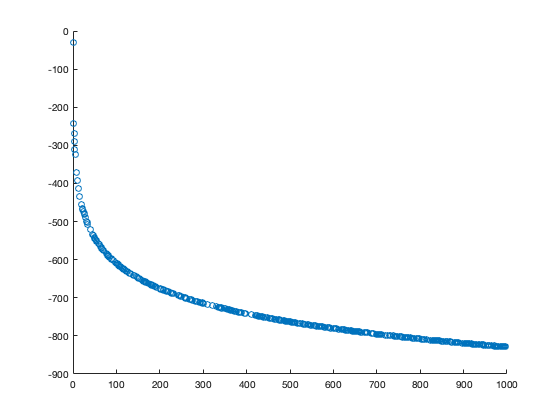

%Generate Problem

%Psudo Generated Random Parameters
a = - 100 + 200*rand(1);
b = -50 + 100*rand(1);
c = -30 + 60*rand(1); 

%Generate Randomly Sampled Data
data = 1000 * rand(500,1);
f = @(x) a * log(b * x) + c;
vals = f(data);

%Plot
scatter(data,vals);

## Seems to be logrithmic

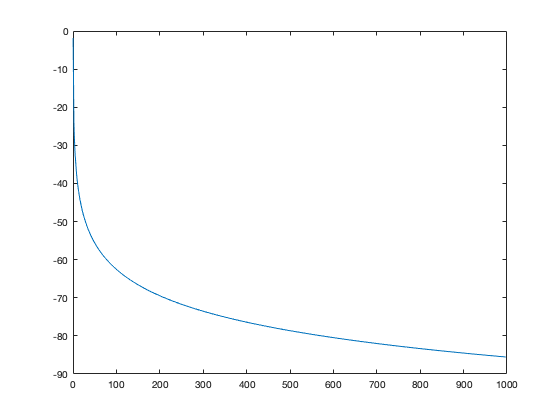

%Lets start by trying to guess the parameters to this line

data = sort(data);
g = -10 * log(5.2 .* data) + 0;

plot(data,g);


%Initial Guess
aGuess = -200;
bGuess = 5.2;
cGuess = 0;

## Not too far off: Lets try gradient descent with our guess

data = [data vals];
p = [aGuess; bGuess; cGuess];
params = GradientDescent(@gr,data,p,300,.001);

disp(params);

   1.0e+02 *

  -2.0000 - 0.0000i
   0.0520 + 0.0000i
   0.0000 - 0.0000i



disp(a);

  -95.4281



disp(b);

   -5.0596



disp(c);

  -15.3816



function [r1,r2,r3] = gr(params,x)

r1 = 2*(params(1)*log(params(2)*x(1,1)) + params(3) - x(1,2)) * (log(params(2) * x(1,1)));
r2 = 2*(params(1)*log(params(2)*x(1,1)) + params(3) - x(1,2)) * (params(1)/(params(2) * x(1,1)));
r3 = 2*(params(1)*log(params(2)*x(1,1)) + params(3) - x(1,2));
end